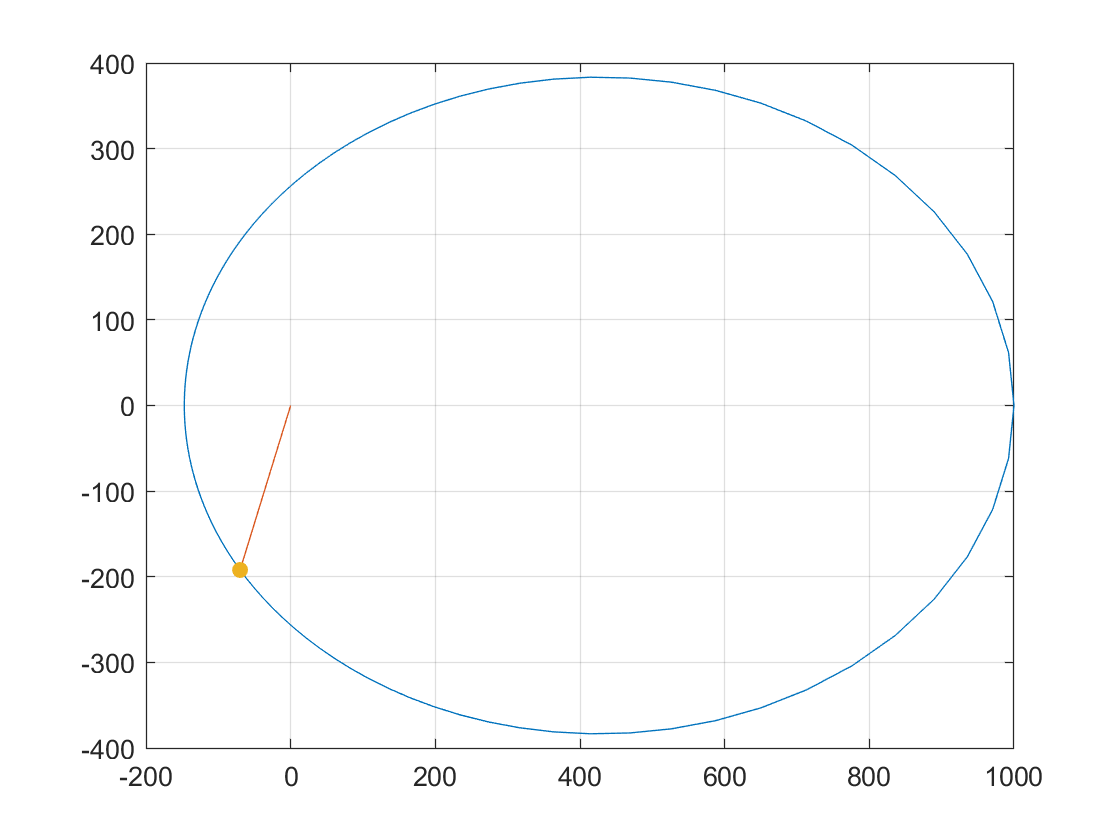

%Lagrange F&G solution plotter
%Ari - ari@gereshes.com
close all

r_0=[1000,0,0]';%Define initial conditions
v_0=[0,10,0]';
f_0=0;

mu=3.9E5;
h=norm(cross(r_0,v_0));
p=(h^2)/mu;
points=100;

%Defining holder variable
fHolder=linspace(0,360,points+2);
fHolder=fHolder-f_0;
fHolder=fHolder*pi/180;
rVec=zeros(3,points+2);
vVec=zeros(3,points+2);

%Calcualting some constants
r0=norm(r_0);
sig0=(r_0'*v_0)/sqrt(mu);

%Computing the F&G solution at different points
for c=1:points+2
    theta=fHolder(c);
   
   rDen=r0+((p-r0)*cos(theta))-(sqrt(p)*sig0*sin(theta));
   r=p*r0/rDen;
   F=1-(r*(1-cos(theta))/p);
   G=r*r0*sin(theta)/sqrt(mu*p);
   Ft=(sig0*(1-cos(theta)))-(sqrt(p)*sin(theta));
   Ft=Ft*sqrt(mu)/(r0*p);
   Gt=r0*(1-cos(theta))/p;
   Gt=1-Gt;
   rVec(:,c)=(F*r_0)+(G*v_0);
   vVec(:,c)=(Ft*r_0)+(Gt*v_0);
end

%Play with the slider to change the true anomaly of the satellite
theta=250;
theta=theta+f_0;
rDen=r0+((p-r0)*cosd(theta))-(sqrt(p)*sig0*sind(theta));
   r=p*r0/rDen;
x=[0,r*cosd(theta)];
y=[0,r*sind(theta)];

%Plotting
plot(rVec(1,:),rVec(2,:),x,y);
grid on
hold on
scatter(x(2),y(2),'filled')